# MPC with Feedforward in Control101

This livescript is a brief manual in support of the app ***mpcfeedforward_control101.mlapp***.   This is a simple interface to understand and investigate how the use of feedforward information on the target in an MPC law affects the decision making and performance.

Predictions are core to the advanced control technique of model predictive control (MPC) and thus understanding their role is essential before engaging with MPC. The tuning parameters dictate the performance index used to determine the 'optimal' current control and thus their choice is important. However, it can be seen that different choices lead to hugely variable behaviour and thus understanding what constitute good and bad choices is essential. The case of feedforward is a special case of this whereby, ironically, using too much information about the future can be counter-productive and this app allows users to explore this issue.

- For more help on how to get the most of this app, please see the videos [here](https://www.youtube.com/playlist?list=PLs7mcKy_nInHEjth9P3m_bxd6D24IVSzz).

- For more information on the supporting files for MPC, please see the following livescripts: ***mpcsourcecode_control101.mlx.***

For more background on MPC readers can look at the website [https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook) and also a range of popular text books such as that by the author: **A first course in predictive control: 2nd Edition**,  J.A. Rossiter, CRC Press (Taylor and Francis group), 2018, ISBN 9781138099340.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- MPC context

- Forming predictions and optimisation

- Interface and user interaction

## 1. MPC context

MPC is a control strategy which bases the choice of control input u(k) on the expected system output behaviour y(k), that is the system predictions. In essence, at each sampling instant:

- Postulate a possible future sequence of inputs u(k), u(k+1), ... .

- Evaluate the corresponding future outputs y(k+1|k), y(k+2|k),... .

- Assign some performance measure J(k) to the input/output prediction pair.

- Through some appropriate search over a range of possible future input sequences, determine the one which gives the best expected performance and use the first element of this sequence, that is u(k).

Details of MPC are discussed in detail in the manual ***mpctuning_control101_manual.mlx,*** so that background is not repeated here.  Rather, the focus here is on what happens when information on the future target is included in the optimisation.

## 2. Forming predictions and optimisation

For simplicitly this app focuses on linear SISO models, although the same principles can be used for non-linear and MIMO models, albeit the coding is somewhat more challenging. 

### 2.1 Prediction matrices 

Without going into details it can be shown that the predictions can be evaluated as matrix vector multiplication, that is:


$$\left\lbrack \begin{array}{c}
y\left(k+1|k\right)\\
y\left(k+2|k\right)\\
\vdots \\
y\left(k+n|k\right)
\end{array}\right\rbrack =H\left\lbrack \begin{array}{c}
u\left(k|k\right)\\
u\left(k+1|k\right)\\
\vdots \\
u\left(k+n-1|k\right)
\end{array}\right\rbrack +P\left\lbrack \begin{array}{c}
u\left(k-1\right)\\
u\left(k-2\right)\\
\vdots \\
u\left(k-m\right)
\end{array}\right\rbrack +Q\left\lbrack \begin{array}{c}
y\left(\textrm{kk}\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack +L\;o$$


where the matrics $H,P,Q$ depend upon the system model and the term $L\;o$ is to deal with disturbances and parameter uncertainty.

### 2.2 Automated decision making and target information

A typical performance measure is given as follows :


$$J=\sum_{i=1}^{\mathrm{ny}} {\left(r\left(k+i|k\right)-y\left(k+i|k\right)\right)}^2 +\lambda \sum_{i=0}^{\mathrm{nu}} \Delta u{\left(k+i|k\right)}^2 ;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=u\left(k\right)-u\left(k-1\right)$$


The parameters ny, nu and $\lambda$ are choices: over what horizon do you wish to assess the output predictions, how many changes to the input value will you be making in the predictions and how much do you weight input changes compared to prediction errors. 

However, of more importance in this resource is the inclusion of the terms $r\left(k+i|k\right)$. The earlier resources made the assumption:


$$\left.r\left(k+i|k\right)=r\left(k+1\right)|k\right),i=1,2,\ldotp \ldotp \ldotp$$


However, what if that is not true. What if we know the future target up to na steps ahead so instead we have the assumption:


$$\begin{array}{l}
\left.r\left(k+i|k\right)=r\left(k+i\right)\right),i<n_a \\
r\left(k+i|k\right)=r\left(k+n_a \right),i\ge n_a 
\end{array}$$


### 2.3. Philisophical discussion

In principle you would think that knowing more about the future requirements would enable better planning, but interestingly that is not the case with MPC because, for computational and other reasons, MPC works with a finite number of degrees of freedom.

Because MPC has finite degrees of freedom, it is not useful to be too ambitious in what you want to achieve.  For example:

**Mind experiment**: You want well cooked bread for tea tomorrow at 4pm, however your main degrees of freedom are an ability to turn the oven on and off today! Clearly there is a significant mismatch between the degrees of freedom available to you and the objective you have set.

A summary observation is that providing target information that is not temporally aligned with your input choices is unhelpful at best and indeed can be worse.

### 2.4. Proposal for advance knowledge

The input degrees of freedom needed to be temporally matched with the target changes we want to follow, if not, those degrees of freedom are not useful beyond steady-state matching. IN consequence a simplistic proposal is that 'advance knowledge' na should follow a rule something like:

$n_a \approx n_u$ or more realistically  $n_a -n_u \le \beta$ where $\beta$ is a small enough integer, typically around the rise time of the process.

The purpose of the app is to allow users to explore this proposal and decide for themselves what is a sensible amount of advance knowledge to use.

**Remark**: Infinite horizon MPC algorithms also have finite degrees of freedom and implicitly thus have a similar issue which is linked to the chosen terminal region.

## 3 Interface and user interaction

The main purpose of the app is to allow users to visualise the impact of changing prediction horizons and weights on the closed-loop behavour for a range of models and scenarios. The use of the app is largely self-explanatory, but a few examples are given here for completeness.

it is straightforward to choose the comparisons that you want and overlay all of these scenarios. Use the refresh button to clear the figures and begin again. The legend keeps track of the choices you have made.

### 3.1 Scenarios and models

The app has pre-defined models coded and the user must select from these. Similarly there are limits to the choices of horozons and weights allowed. For users who wish to experiment with their own scenarios, models and horizons, please see the file **mpcsourcecode_control101.mlx** for more guidance.

The specific models coded into the app are as follows:


$$G=\frac{0\ldotp 4z^{-1} }{1-0\ldotp 8z^{-1} };\;G=\frac{0\ldotp 1z^{-1} +0\ldotp 1z^{-2} }{1-1\ldotp 4z^{-1} +0\ldotp 48z^{-2} };\;\;G=\frac{0\ldotp 05z^{-1} +0\ldotp 03z^{-2} }{1-1\ldotp 9z^{-1} +1\ldotp 18z^{-2} -0\ldotp 24z^{-3} };\;$$


### 3.2 Disturbances and uncertainty

Users can add some authenticity to the simulations to observe how well MPC deals with a more realistic scenario. The particular uncertainty allowed is:

- Output disturbances. This is introduced mid-simulation so that the user can observe how well MPC deals with it and also compare behaviour with and without the disturbance.

- Parameter uncertainty. For simplicitly the parameter errors are fixed in the code. In essence the control is designed on the assumed model, but the simulation is performed on the true system which is slightly different.

### 3.3 Numerical assessments

The app keeps track of 3 different values that may be of interest.

Sum of output tracking errors: $\sum_{i=1}^{\textrm{ny}} {\left(r-y\left(k+i|k\right)\right)}^2 ;$

Sum of input changes: $\sum_{i=0}^{\textrm{nu}} \Delta u{\left(k+i|k\right)}^2 ;$   (note the weighting $\lambda$ is ignored here)

MPC cost function:   $J=\sum_{i=1}^{\textrm{ny}} {\left(r-y\left(k+i|k\right)\right)}^2 +\lambda \sum_{i=0}^{\textrm{nu}} \Delta u{\left(k+i|k\right)}^2 ;$

### 3.4. Illustrations of the app

- The first example in Figure 4.1 shows how performance improves for small increases in na, but as na goes beyond 3, then performance begins to deteriorate again. So the use of advance knowledge becomes counter productive.

- The 2nd example in Figure 4.2 increases the control horizon and this makes MPC better able to make use of the advance knowledge so performance improves as na increases. nevertheless, one may question whether all the preliminary control moves 5-6 steps ahead are a good thing in reality!

- Figure 3 shows anothe example where small increases in na help, but larger increases do not.

- Users are encourage to create their own experiments and explore the issue for a range of different tunings.

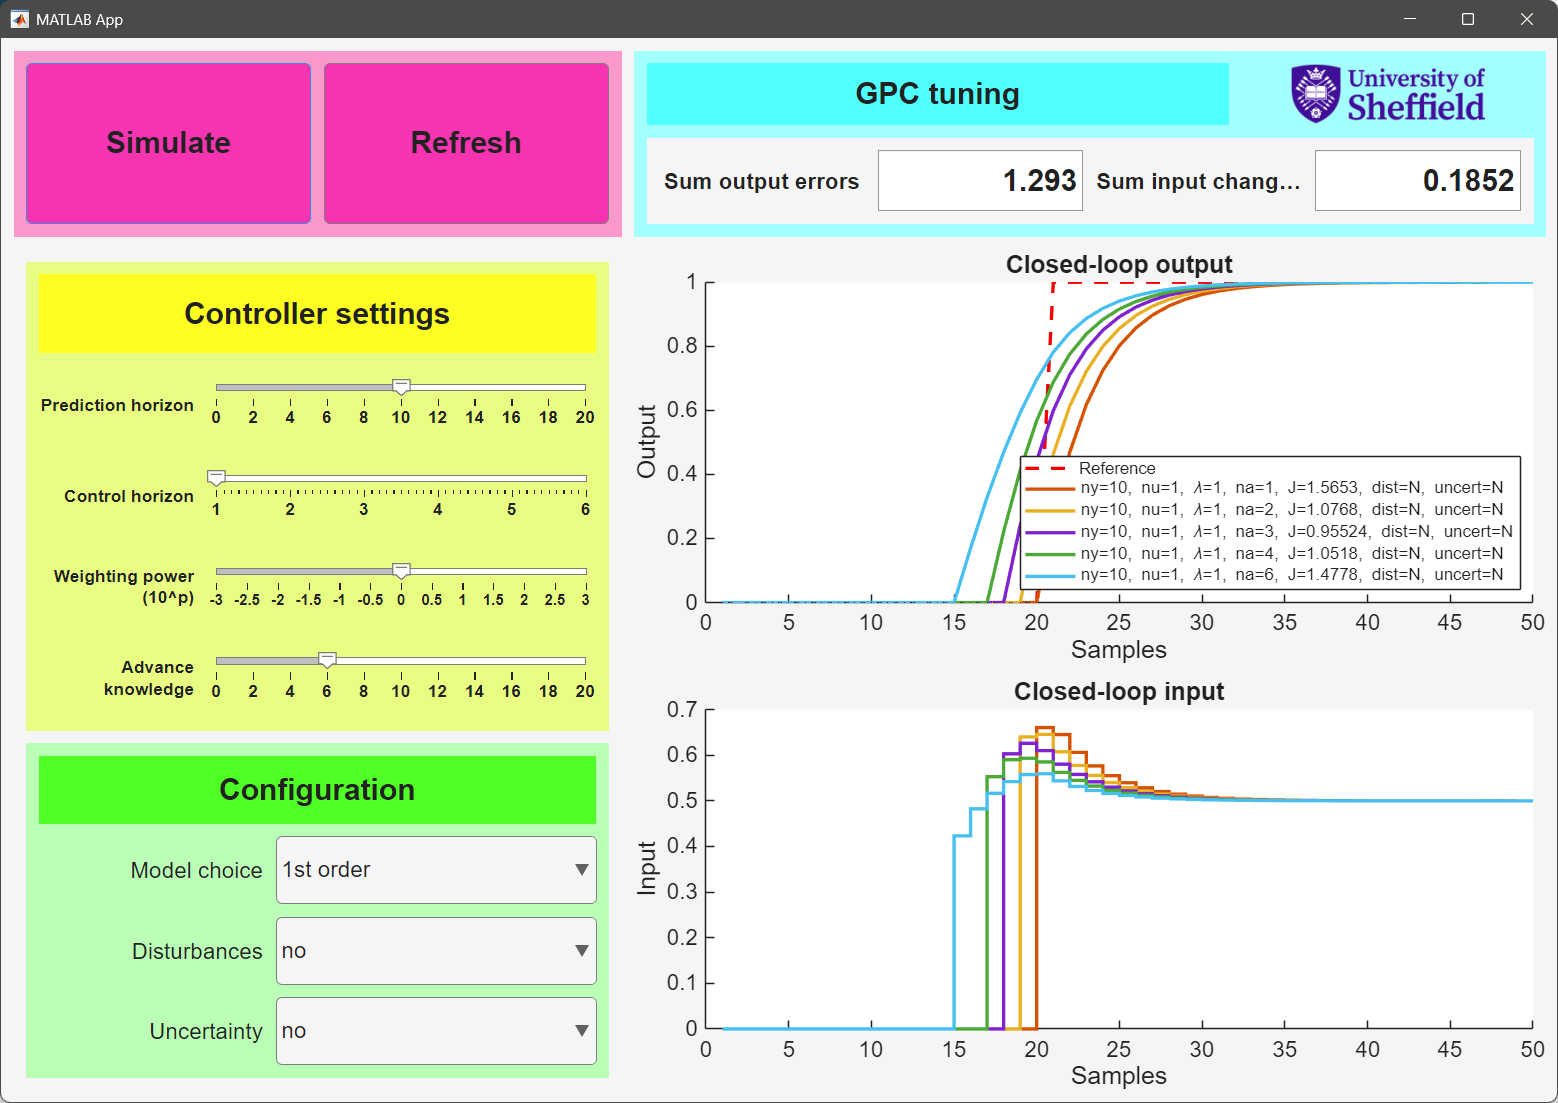

**Figure 4.1 **1st order model, changing the advance knowledge

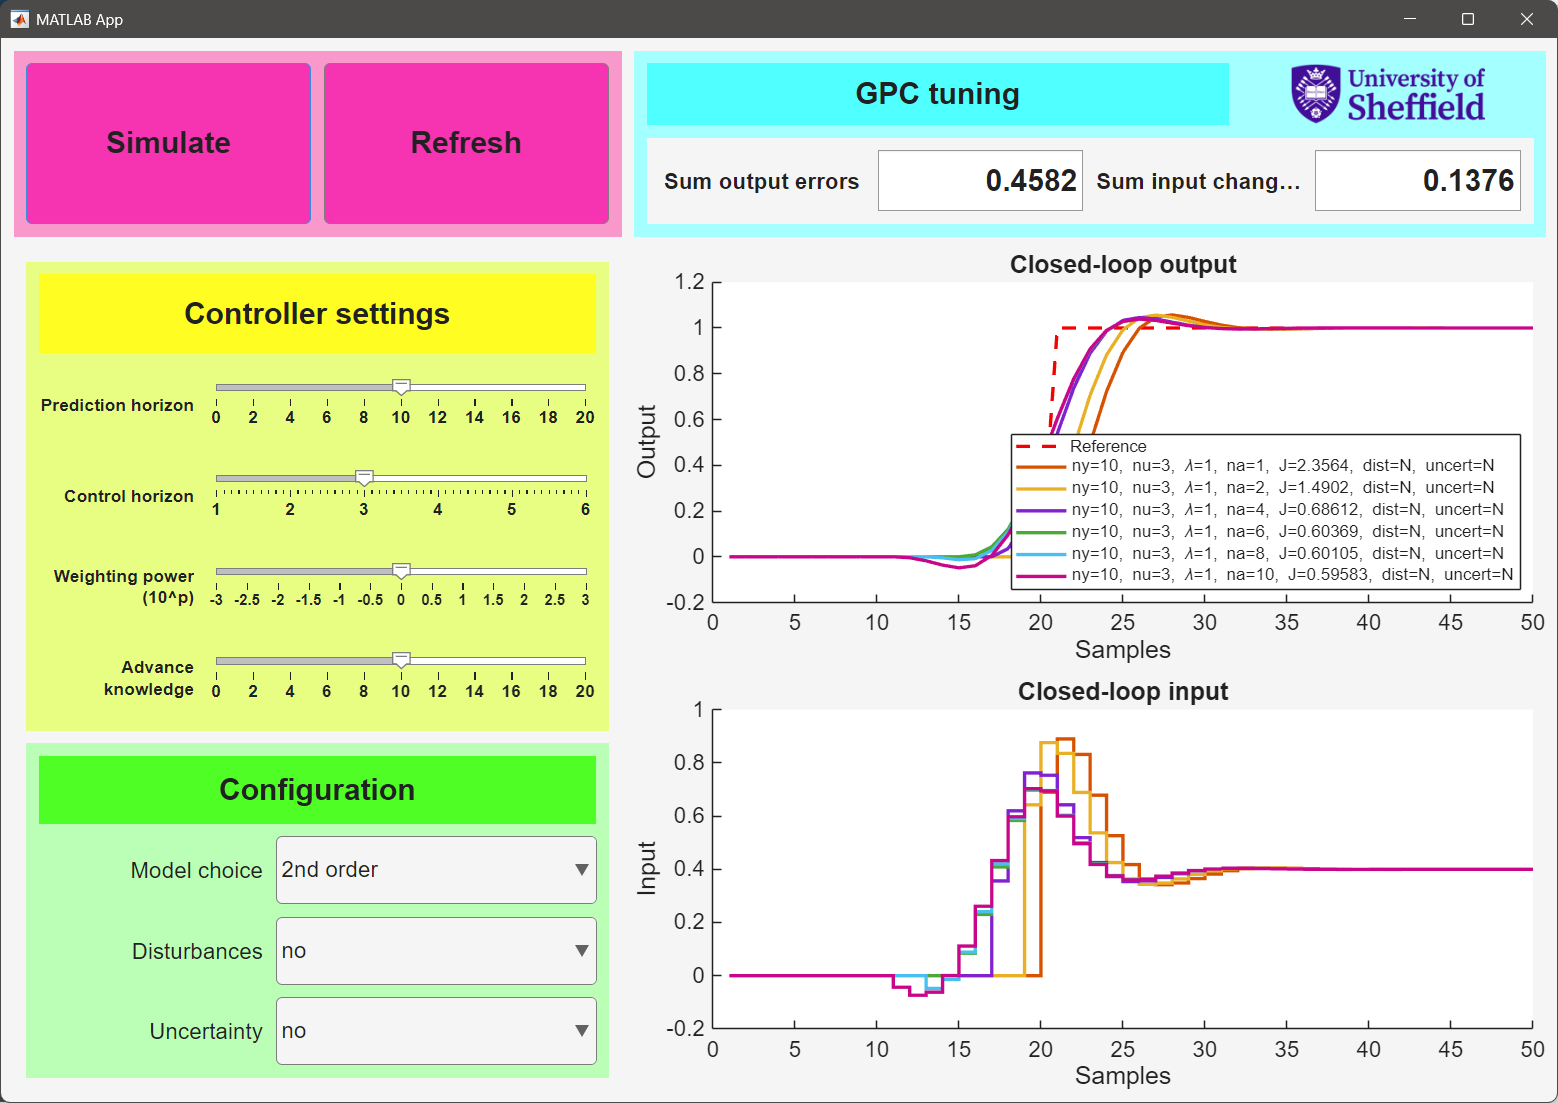

**Figure 4.2** 2nd order example, impact of changing advance knowledge

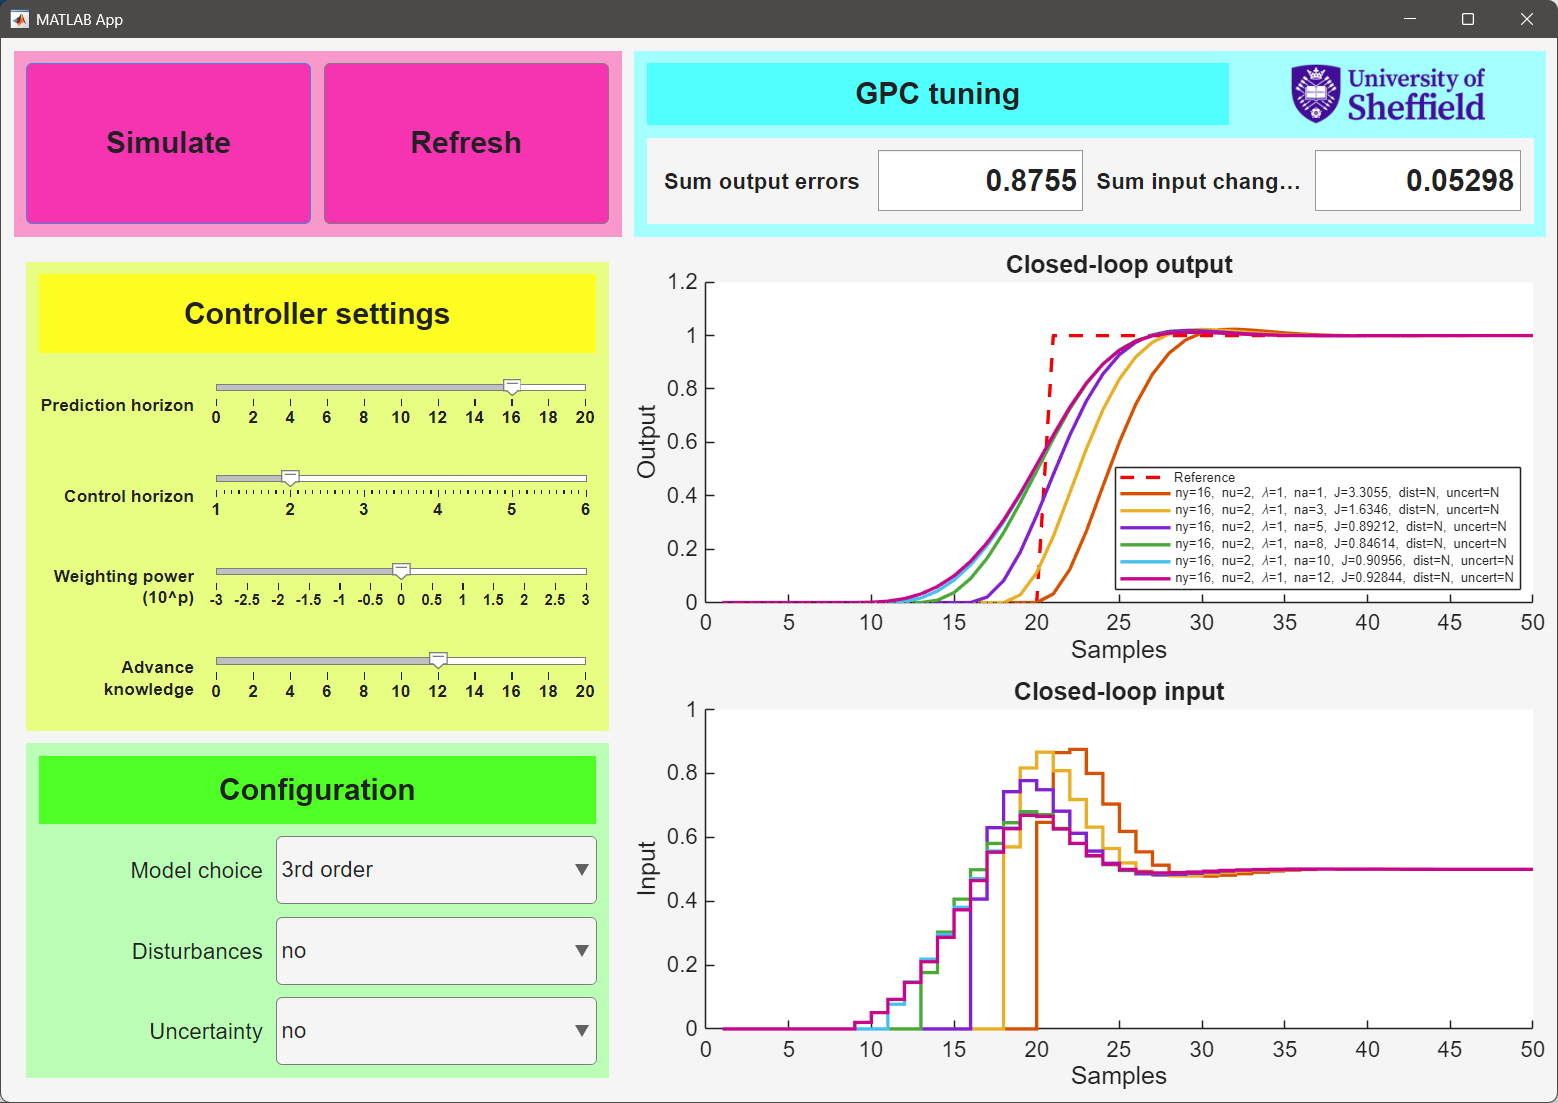

**Figure 4.3** 3rd order example, impact of changing advance knowledge